## `Residual-Aware RL-MPC`

## `Baseline MPC Design`

close all hidden; clear; clc;
rng(418);

### 1. Load N4SID Model

load('data/identified_models.mat');
A = A_n4; B = B_n4; C = C_n4; 

[nx, nu] = size(B);
ny = size(C, 1);

### **2. Baseline MPC Parameters**

We select a prediction horizon (Np=30) sufficiently long to capture the swinging dynamics, while keeping the control horizon shorter for low computational cost. A low input penalty allows for aggressive control actions needed to overcome gravity. Seen in the simulation script, baseline MPC is still not sufficently aggressive to overcome the sinusiodal hill.

Np = 30;             % Prediction Horizon
Nc = 10;             % Control Horizon
Q_weight = 10;       % Weight on Tracking
R_weight = 0.1;      % Weight on Input

% Constraints
u_max = 1.0;
u_min = -1.0;
du_max = 0.5;

### 3. Build Prediction Matrices

% F Matrix
F = zeros(Np*ny, nx);
Ap = A;
for k = 1:Np
    F(k,:) = C * Ap;
    Ap = Ap * A;
end

% H Matrix and Phi
H = zeros(Np*ny, Nc*nu);
for i = 1:Np
    for j = 1:Nc
        if j <= i
            if (i-j) == 0
                term = C * B;
            else
                term = C * (A^(i-j)) * B; 
            end
            H(i, j) = term;
        end
    end
end

S = tril(ones(Nc));
Phi = H * S;

% Cost Matrices
Qbar = Q_weight * eye(Np);
Rbar = R_weight * eye(Nc);

% Hqp computation
Hqp = Phi' * Qbar * Phi + Rbar;
Hqp = 0.5 * (Hqp + Hqp');

### 4. Simulation Setup

The simulation loop pits the linear N4SID model against the true nonlinear Gym physics. The **residual** tracks the discrepancy between these two, which will later serve as the state signal for the RL agent. Detailed info can be found at visualize_results.ipynb .

T_final = 300;
ref_val = 0.45; % Goal, flag

% Initial Real Plant Physical Conditions
x_true = [-0.5; 0]; 

% Start at zero (equilibrium)
x_model = zeros(nx, 1); 
u_prev = 0;

log_y = zeros(T_final, 1);
log_u = zeros(T_final, 1);
log_r = zeros(T_final, 1); % Residual

% Constraint Matrices
A_du = [eye(Nc); -eye(Nc)];
b_du = [du_max * ones(Nc,1); du_max * ones(Nc,1)];
A_u = [S; -S]; 
options = optimoptions('quadprog', 'Display', 'off');


for k = 1:T_final

    r_window = ref_val * ones(Np, 1);
    
    % Prediction from Model State
    u_base = u_prev * ones(Nc, 1);
    bk = F * x_model + H * u_base;
    fqp = Phi' * Qbar * (bk - r_window);
    b_u = [u_max * ones(Nc,1) - u_base;
           -u_min * ones(Nc,1) + u_base]; 
    
    % Solve QP
    Aineq = [A_du; A_u];
    bineq = [b_du; b_u];
    [dU, ~, exitflag] = quadprog(Hqp, fqp, Aineq, bineq, [], [], [], [], [], options);
    if exitflag < 0
        du = 0; 
    else
        du = dU(1);
    end
    
    u_apply = u_prev + du;
    
    % Predict next state output using the model (Before physics update)
    x_model_next = A * x_model + B * u_apply;
    y_pred_next = C * x_model_next;

    % Update Real Physics
    curr_pos = x_true(1);
    curr_vel = x_true(2);
    pow = 0.0015;
    force = max(min(u_apply, 1.0), -1.0);
    new_vel = curr_vel + force * pow - 0.0025 * cos(3 * curr_pos);
    new_vel = max(min(new_vel, 0.07), -0.07);
    new_pos = curr_pos + new_vel;
    
    % Wall collisions
    if new_pos <= -1.2, new_pos = -1.2; new_vel = 0; end
    if new_pos >= 0.6, new_pos = 0.6; new_vel = 0; end
    x_true = [new_pos; new_vel]; 
    
    % Calculate Residual
    residual = abs(new_pos - y_pred_next);
    x_model = x_model_next;

    % Logging
    log_y(k) = new_pos;
    log_u(k) = u_apply;
    log_r(k) = residual;
    u_prev = u_apply;
end

### 4. Visualization

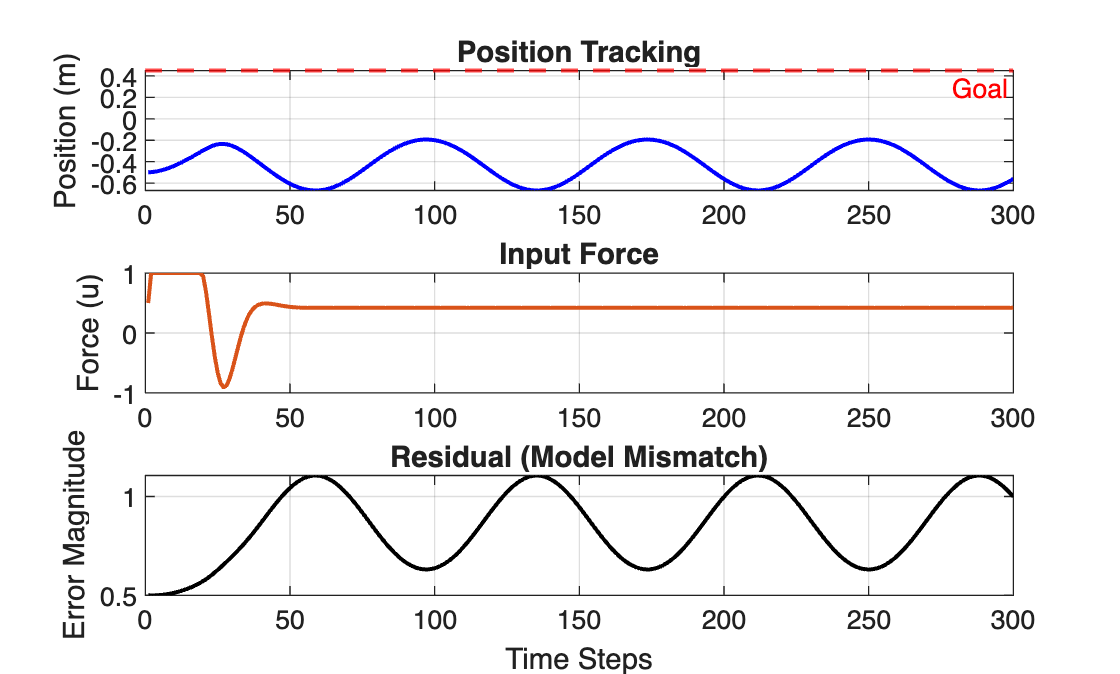

t_vec = 1:T_final;
figure('Name', 'MPC Baseline Results', 'Color', 'w');

subplot(3,1,1);
plot(t_vec, log_y, 'b', 'LineWidth', 1.5); hold on;
yline(ref_val, 'r--', 'Goal', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');
title('Position Tracking', 'FontWeight', 'bold'); 
ylabel('Position (m)');
grid on;
set(gca, 'FontSize', 10, 'Box', 'on'); 

subplot(3,1,2);
plot(t_vec, log_u, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1.5);
title('Input Force', 'FontWeight', 'bold'); 
ylabel('Force (u)');
grid on;
set(gca, 'FontSize', 10, 'Box', 'on');

subplot(3,1,3);
plot(t_vec, log_r, 'k', 'LineWidth', 1.5); 
title('Residual (Model Mismatch)', 'FontWeight', 'bold'); 
xlabel('Time Steps'); 
ylabel('Error Magnitude');
grid on;
set(gca, 'FontSize', 10, 'Box', 'on');


save('data/mpc_results.mat', 'log_y', 'log_u', 'log_r');
fprintf('Results saved to data/mpc_results.mat\n');

Results saved to data/mpc_results.mat
